# Произвольный сигнал из суммы гармоник

Создание произвольного периодического сигнала из суммы нечётных гармоник

Зададим вектор времени с шагом 0.1

t = 0:0.1:10;

Сложим 1, 3, 5, 7 и 9 гармоники. Отразим их сумму на графиках.

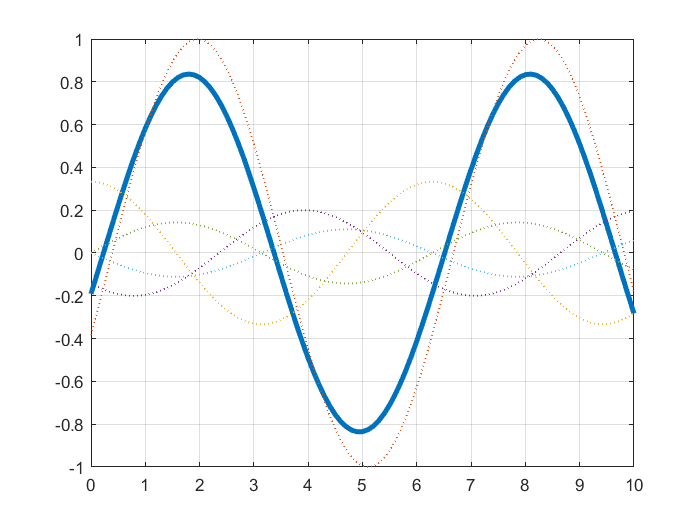

%p = [0 0 0 0 0];
p = [-pi/8 pi/2 -3*pi/4 0 pi];

y1 = sin(t+p(1));
y3 = sin(t+p(2))/3;
y5 = sin(t+p(3))/5;
y7 = sin(t+p(4))/7;
y9 = sin(t+p(5))/9;

plot(t, (y1+y3+y5+y7+y9), 'LineWidth',3); grid on; hold on;
plot(t, y1, t, y3, t, y5, t, y7, t, y9, 'LineWidth', 1, 'LineStyle', ':');
hold off;